# Week 1

CoolProp reminder

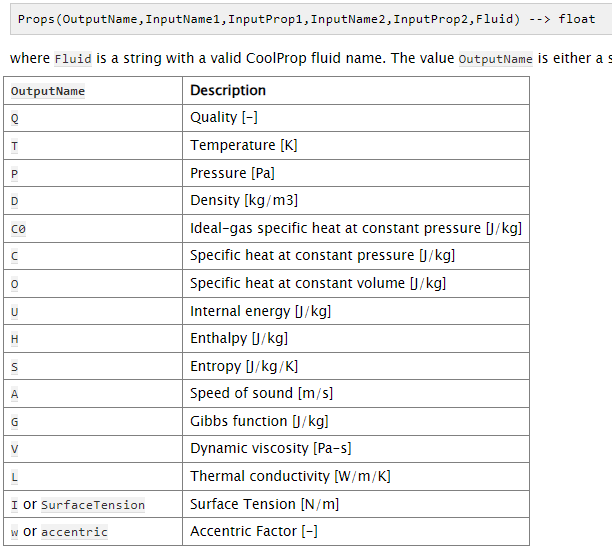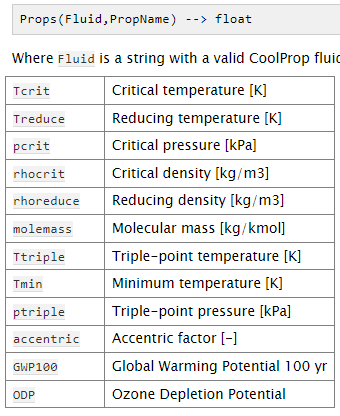

clc; clear;

CP = py.importlib.import_module("CoolProp.CoolProp");



format bank

fluid = "R134a";
mdot = 0.05;
p1 = 2e5;
p2 = 8e5;

x = 1;

eta_is = 0.7;


h1 = CP.PropsSI("H", "P", p1, "Q", x, fluid);
s1 = CP.PropsSI("S", "P", p1, "Q", x, fluid);
h2s = CP.PropsSI("H", "P", p2, "S", s1, fluid);
h2_forsjov = (h2s - h1)/eta_is + h1;

P_axel = mdot*(h2s - h1)/eta_is % watt

P_axel =        2056.50


P_axel2 = mdot*(h2_forsjov - h1) % watt

P_axel2 =        2056.50


format bank
% water
kelvin = 273.15;
density = 1000;
cp = 4180;
fluid = "water";
U = 500;

% HX
nPlates = 10;
A = 0.07*0.2 * nPlates;

% Bruser
tcIn_b = 10;
mdot_b = 10/60; % kg/s

% Fjernvarme
tcIn_fj = 60;
mdot_fv = 350/3600; % kg/s

syms tcOut_b tcOut_fj

LMTD = ((tcIn_fj- tcOut_b) - (tcOut_fj-tcIn_b))/(log(((tcIn_fj- tcOut_b))/(tcOut_fj-tcIn_b)));
Q_lmtd = U*A*LMTD;

Q_b = mdot_b * cp * (tcOut_b - tcIn_b) == Q_lmtd;
Q_fj = mdot_fv * cp * (tcIn_fj - tcOut_fj) == Q_lmtd;


eqs = [Q_b; Q_fj];

sols = vpasolve(eqs, symvar(eqs))

sols = struct with fields:
     tcOut_b: 14.419383403155244444327525523356
    tcOut_fj: 52.423914166019580952581384817104




% MED VIRKNINGSGRAD I STEDET
syms tcOut_b tcOut_fj 
Q_ideal = mdot_fv * cp * (tcIn_fj - tcIn_b);
eta = 0.6;
Q_act = Q_ideal * eta;

t_Q_b = mdot_b * cp * (tcOut_b - tcIn_b) == Q_act;
t_Q_fj = mdot_fv * cp * (tcIn_fj - tcOut_fj) == Q_act;

eqs = [t_Q_b; t_Q_fj];

sols_eta = vpasolve(eqs, symvar(eqs))

sols_eta = struct with fields:
     tcOut_b: 27.5
    tcOut_fj: 30.0
